clc; clear; close all;

K = 1;
tau = 0.5;
G = tf(K,[tau 1]);

Kp = 2.5;
Ki = 3;
Kd = 0.15;

C = pid(Kp,Ki,Kd);

T_pid = feedback(C*G,1);

figure;
step(T_pid);
title('PID Controlled Response');
xlabel('Time (s)');
ylabel('Motor Speed');

info = stepinfo(T_pid)

info = struct with fields:
         RiseTime: 0.8688
    TransientTime: 2.4901
     SettlingTime: 2.2457
      SettlingMin: 0.9009
      SettlingMax: 0.9996
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9996
         PeakTime: 5.9552


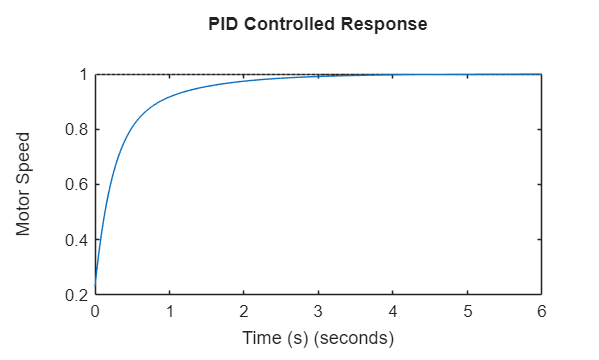


if ~exist('results','dir')
    mkdir('results');
end

saveas(gcf,'results/pid_response.png');


save('pid_data.mat','T_pid','G');